# Average channel gain with interference

Consider the multi-cell scenario.

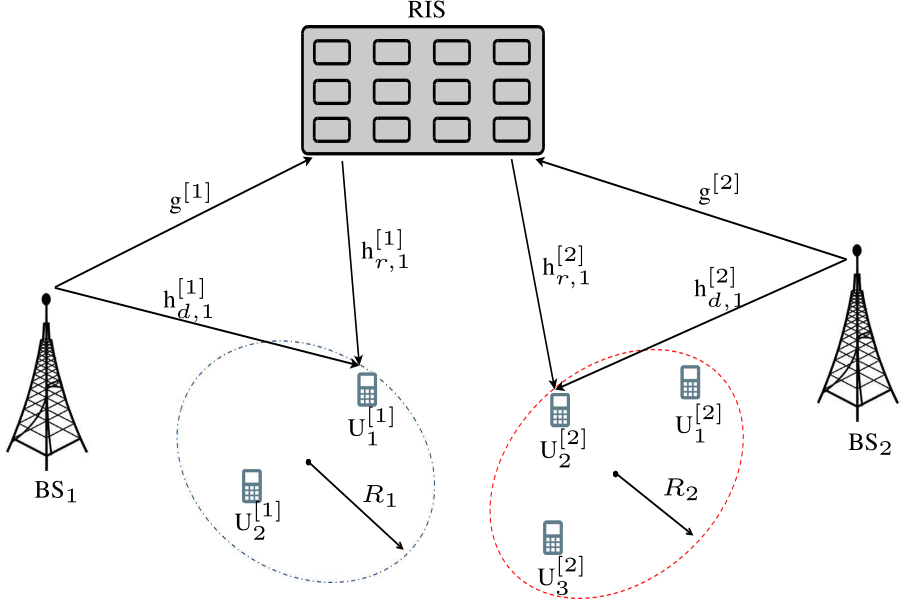

Here, we need to know if the channel gain and its mean is dependent on the RIS elements tuned for the other basestation.


$$$
R_{k,m} = log_2(1+\frac{ |h_{k,m}|^2 \alpha_{k,m}P_T }
	{|h_{k,m}|^2\sum_{j=k+1}^{N_m}\alpha_{j,m} + \sigma^2})
\\
	h_{k,1} = \sum_{i=1}^{N}a_{i1}h^r_{i,k}e^{j\theta_{i,1}}g_i + \sum_{i=1}^{N}a_{i2}h^r_{i,k}e^{j\theta_{i,2}}g_i + h^d_{k,1}$$$


This is what we cal interference here:


$$I=\sum_{i=1}^{N}a_{i2}h^r_{i,k}e^{j\theta_{i,2}}g_i $$


We can see from the results that the channel gain of users will increase on average when there are a couple of RIS elements on and configured randomly.

We have also investigated the effect of these elements on achievable rate of $BS_1$users.

%% Before we start
clc
close all
addpath('C:\Users\Asus irG\Documents\GitHub\RIS-Sharing-Scenario\modules\') % You need to change the address in case you run it on your computer

%% Parameters

% Number of users in the first and second basestation areas
N1 = 3;
N2 = 3;

% Radius of the user area center for BS1 and BS2
R1 = 10;
R2 = 10;

% Number of IRS elements
N_i = 24;
q_t = 1/8;                  % Quantization step-size

% Number of iterations for the simulation
N_iter = 2;

% Scenario variable
SV = 3;

% Transmit power of the basestations (in watts)
P_T = (10^(40/10)) * 1e-3;

% Locations of the basestations (BS1 and BS2) and the IRS
[x1 , y1 , z1] = deal(0 , 0 , 0);
[x2 , y2 , z2] = deal(100 , 10 , 0);
[x_i , y_i , z_i] = deal(50 , 30 , 10);

% Number of transmitter and receiver antennas
M_t = 1;
M_r = 1;

% Distance between IRS and BSs
d_IB = 100;

% Path loss exponent parameters for distance and height
alpha_d = 3.76;
alpha_r = 2;

% System bandwidth (in Hz)
BW = 10e7;

% Noise power (in watts)
noise_power = (10^(-114/10));

% Interference existence between BSs (1 for considering interference)
interference = 1;

% Error tolerance parameter
epsilon = 0.05;
discrete = false;           % Discrete mode for optimization
MAC = 'NOMA'

%% users location
x = zeros(N1+N2 , 1) ; 
y = zeros(N1+N2 , 1) ; 
z = 1.5 * ones(N1+N2 , 1) ; 
x(1 : N1 , 1) = 35 ; 
x(N1+1 : N2+N1) = 55 ; 
y(1 : N1 , 1) = 25 ; 
y(N1+1 : N2+N1) = 10 ; 

Lets say 2 tiles are allocated to BS1 and $$N_{i2}$$ is allocated to BS2.

%% Calculating Rates
N_i1 = floor((3 - 1) * N_i * q_t);     % No. of elements allocated to BS1

|....
||...
|||..
||||.
|||||


Elapsed time is 295.046078 seconds.


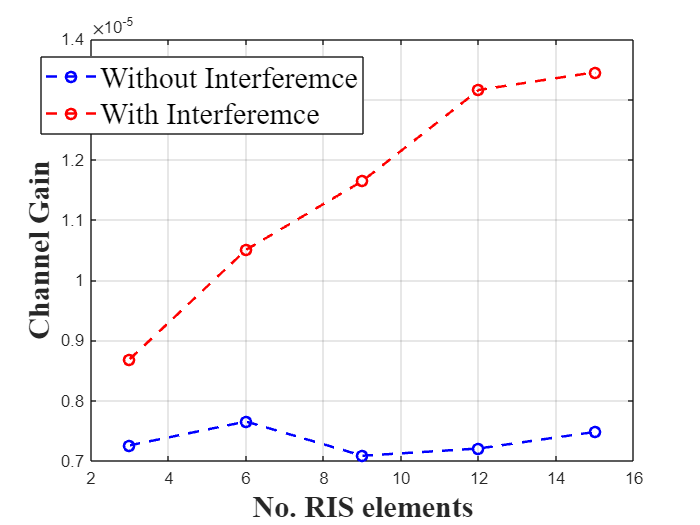

rate = zeros(ceil(1 / q_t) + 1, ceil(1 / q_t) + 1, 2, SV);
channel_gain11 = zeros(N1, SV);
channel_gain12 = zeros(N1, SV);
rate1 = zeros(SV, 1); % rate without interference
rate2 = zeros(SV, 1); % rate with interference

start = 1;   
step = 1;     
m = repmat('.', 1, SV);

tic

for N_i2 = floor(N_i * q_t * (start : step : (SV - 1) * step + start))
    i = 1 + floor((N_i2 / (N_i * q_t) - start) / step);
    m(i) = '|';
    disp(m)
    
    for j = 1 : N_iter
        % Randomize user positions
        x0 = x;
        y0 = y;
        t = 2 * pi * rand(N1, 1);
        R = [R1; R2];
        radius = R(1) * sqrt(rand(N1, 1));
        x(1 : N1) = x0(1 : N1) + radius .* cos(t);

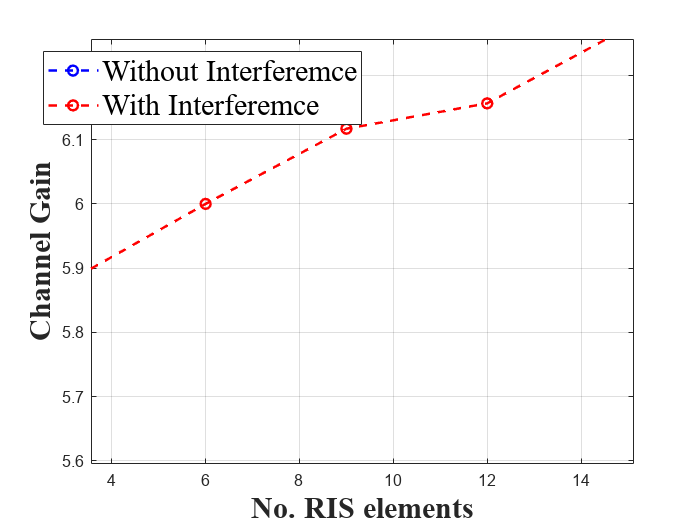

        y(1 : N1) = y0(1 : N1) + radius .* sin(t);

        % Compute channel gains and rates
        [h_d1, G1, h_r1] = ChannelGain(M_t, M_r, N1, N_i, x(1 : N1), y(1 : N1), z(1 : N1), x1, y1,...
                                z1, x_i, y_i, z_i, alpha_d, alpha_r);
        [h_d2, G2, h_r2] = ChannelGain(M_t, M_r, N2, N_i, x(N1 + 1 : N1 + N2), y(N1 + 1 : N1 + N2), z(N1 + 1 : N1 + N2), x2, y2,...
                                z2, x_i, y_i, z_i, alpha_d, alpha_r);

        [~, Z_cvx1] = Rate(h_d1, G1(1 : N_i1), h_r1(1 : N_i1, :), N1, N_i1, P_T, noise_power, N_bits, discrete, MAC);
        [~, Z_cvx2] = Rate(h_d2, G2(1 : N_i2), h_r2(1 : N_i2, :), N2, N_i2, P_T, noise_power, N_bits, discrete, MAC);

        % With interference
        interference = 0;
        Theta = diag([Z_cvx1; interference * Z_cvx2; zeros(N_i - N_i1 - N_i2, 1)]);
        channel_gain11(1 : N1, i) = channel_gain11(1 : N1, i) + abs(h_d1 + h_r1' * Theta * G1);
        [exact_rate1, ~] = SISONoma(epsilon, sort(abs(h_d1 + h_r1' * Theta * G1)).^2 * P_T / noise_power);
        rate1(i) = rate1(i) + exact_rate1;

        % Without interference

        interference = 1;
        Theta = diag([Z_cvx1; interference * Z_cvx2; zeros(N_i - N_i1 - N_i2, 1)]);
        channel_gain12(1 : N1, i) = channel_gain12(1 : N1, i) + abs(h_d1 + h_r1' * Theta * G1);
        [exact_rate2, ~] = SISONoma(epsilon, sort(abs(h_d1 + h_r1' * Theta * G1)).^2 * P_T / noise_power);
        rate2(i) = rate2(i) + exact_rate2;
    end 
end

toc

rate1 = rate1 / N_iter;
rate2 = rate2 / N_iter;
channel_gain11 = 1 * channel_gain11/N_iter ;
channel_gain12 = 1 * channel_gain12/N_iter ;

Here we plot interference effect on the channel gain and achievable rate.

%% Plot Channel Gain
figure

% Draw results
plot(floor(N_i*q_t*(start : step : (SV - 1) * step + start)) , channel_gain11(1 , 1 : SV) , 'b--o' , 'linewidth' , 1.5)
hold on
plot(floor(N_i*q_t*(start : step : (SV - 1) * step + start)) , channel_gain12(1 , 1 : SV), 'r--o' , 'linewidth' , 1.5)

% Legend
lgnd = legend('Without Interferemce' , 'With Interferemce');
set(lgnd,'FontSize',18);
set(lgnd,'FontName','Times New Roman');

grid on
set(gcf , 'color' , 'w');   % Set the figure background to white

% Axes labels and limits
xlabel('No. RIS elements' , 'FontName','Times New Roman', 'FontSize',18 , 'FontWeight', 'bold' )
ylabel('Channel Gain' , 'FontName','Times New Roman', 'FontSize',18 , 'FontWeight', 'bold')
%% Plot Channel Gain
figure

% Draw results
plot(floor(N_i*q_t*(start : step : (SV - 1) * step + start)) , rate1 , 'b--o' , 'linewidth' , 1.5)
hold on
plot(floor(N_i*q_t*(start : step : (SV - 1) * step + start)) , rate2 , 'r--o' , 'linewidth' , 1.5)

% Legend
lgnd = legend('Without Interferemce' , 'With Interferemce');
set(lgnd,'FontSize',18);
set(lgnd,'FontName','Times New Roman');

grid on
set(gcf , 'color' , 'w');   % Set the figure background to white

% Axes labels and limits
xlabel('No. RIS elements' , 'FontName','Times New Roman', 'FontSize',18 , 'FontWeight', 'bold' )
ylabel('Channel Gain' , 'FontName','Times New Roman', 'FontSize',18 , 'FontWeight', 'bold')